# Codificacion Real. 

El siguiente script utiliza algoritmos geneticos con codificacion real para encontrar un maximo de una funcion unidimencional. 

## Codigo Principal

clear;clf; 

## Definir parametros generales.

N = 100;         %Numero de generaciones
ciclos = 30;   %Numero de ciclos de generaciones.
mutacion = 0.7; % Mutacion?
razonmutacion = 0.975;  %Razon de mutacion

% Funcion
funcion = 2;
switch funcion
    case 1
        f1 = @(x) (x.^2 + x).*cos(x);
        x_limits = [-10 10];
        n_var=1;
        
    case 2
        f1 = @(x) -(x+7).^2;
        x_limits = [-20 20];
        n_var =1;
end

% Dominio
xs = linspace(x_limits(1),x_limits(2),100);


## Algoritmos Geneticos

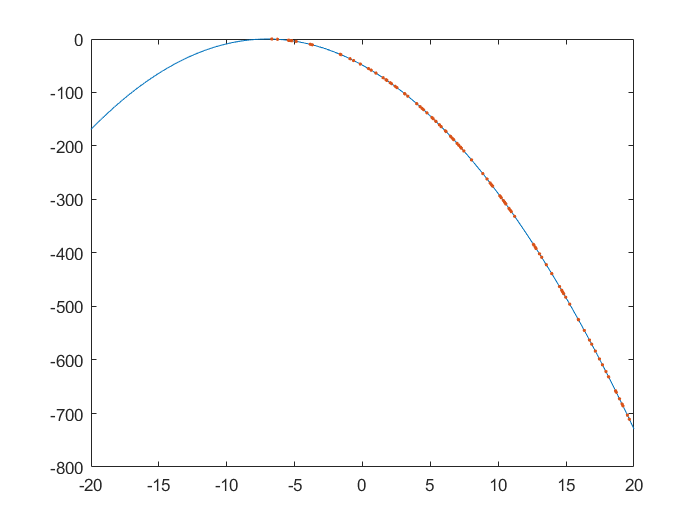

values_max = zeros(ciclos,2);    %Allocar vector de maximos.

% Generacion de la poblacion inicial
rng('default');
pd = makedist('Uniform',-10,10);
hijomutado = random(pd,N,n_var); %La otra opcion es hacer lo matriz.

for nn=1:ciclos
    
    % Evaluacion de la funcion (fitness)
    y = f1(hijomutado);
    
    
    % Plot funcion y soluciones propuestas
    plot(xs, f1(xs), hijomutado, y, '.');
    pause(0.001)


    % Ordena de mejor a peor
    [Individuos,D] = seleccion_CR(hijomutado,exp(y)); % P = exp(y); para evitar negativos
    %Como se busca maximizar, los numeros negativos tendran menor probabilidad
    
    for ii=1:N
        % Seleccion
        p = randsample([1:1:N],2,true,Individuos(:,D+1)); 
        padre1 = Individuos(p(1),1:D);
        padre2 = Individuos(p(2),1:D);
        
        if padre1 == padre2 && ii == 1
            %Si son el mismo padre, agarrar el anterior.
            padre2 = Individuos(p(2)-1, 1:D);
        end
        

        % Cruza
        [hijo] = cruza_CR(padre1, padre2,N);
        
        % Mutacion
        hijomutado = mutacion_CR(hijo,mutacion);
        
        % Condicion para quedarse dentro del dominio de busqueda
        for kk = 1:N
            if abs(hijomutado(kk))> x_limits(2)
                delx = abs(x_limits(2) - abs(hijomutado(kk)));
                hijomutado(kk) = sign(hijomutado(kk))*x_limits(2) - sign(hijomutado(kk))*delx;
            end
        end
        
        
    end
    
    % Cambio en la mutacion
    mutacion = razonmutacion * mutacion;
    % Guerdar valores de maximos
    values_max(nn,1) = max(y);
    values_max(nn,2) = hijomutado(find(y==max(y),1));
    
    
end


values_max(end,2), values_max(end,1)

ans = 12.3252

ans = -0.1011

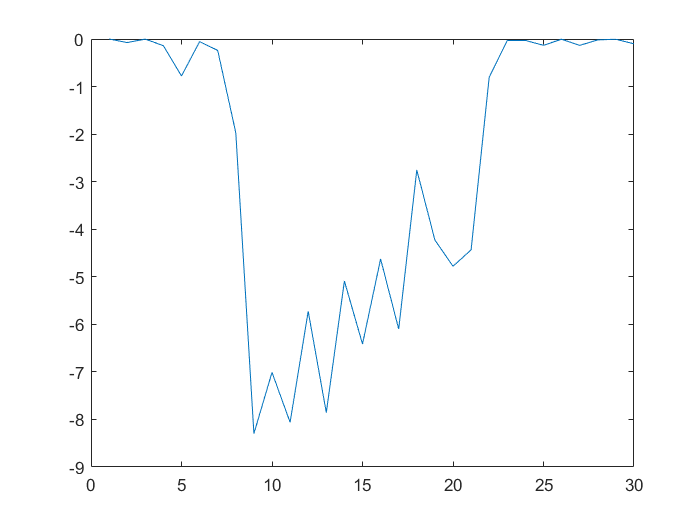


plot(values_max(:,1))

## Funciones

function [M,D] = seleccion_CR(x, y)
% "x" es una matriz con todos los candidatos(poblacion) y "y" es un vector con
% la funcion evaluada en cada x(i). 

    D = size(x,2);

    % Probabilidades
    Prob_y = y./sum(y);
    
    % Llenamos la matriz IndividuosBinarios
    Matriz = zeros(size(x,1), size(x,2)+1);
    Matriz(:,1:D) = x;
    Matriz(:,D+1) = Prob_y(:,1);
    
    % Acomoda la matriz y realiza una suma acumulada para sus probabilidades
    % respectivas
    M = sortrows(Matriz,D+1);
%     M(:,D+1) = cumsum(M(:,D+1));
    
end

function [hijo] = cruza_CR(padre1, padre2,N)

% Licuado
    rng("shuffle")
    pd=makedist("Uniform",0,N); 
    bet = random(pd,1,N);       %N define el numero de hijos que se hacen    
    
    hijo = bet .* abs(padre1) + (1-bet) .* abs(padre2);
    
    hijo = sign(padre1).* hijo'; 
    
end

function [mutado] = mutacion_CR(hijo,gam)

    rng("shuffle")
    pd=makedist("Normal",0,1); 
    Y = random(pd,1,1);   %Cambiar a que sea vector para hacerlo mas robusto.
    % random(pd,1,N) interesante N = length(hijo)
    
    mutado = hijo + gam .* Y; 

end